## SCARA Robot - Lagrangian mechanics example

NB: Links are assumed as thin cuboids for calculating moments of inertia. Torque inputs at the joints for control.

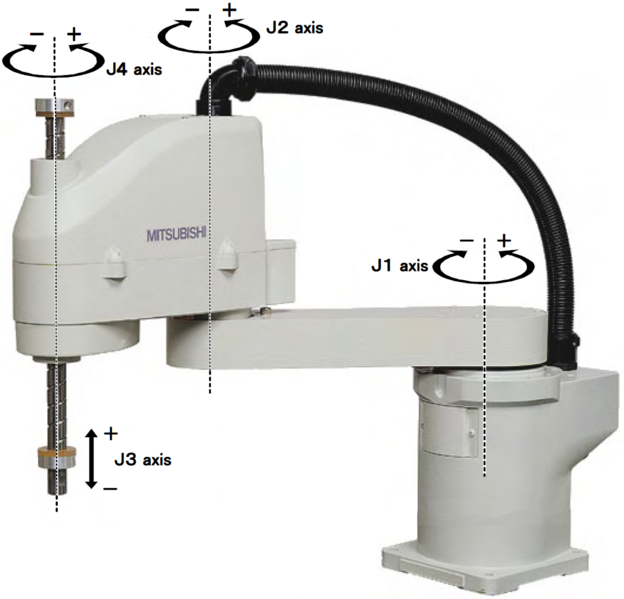

image by (Mitsubishi Electric Automation, Inc. 500 Corporate Woods Pkwy - Vernon Hills, IL - 60061 - US).  License: [https://creativecommons.org/licenses/by-sa/4.0/deed.en](https://creativecommons.org/licenses/by-sa/4.0/deed.en)

Note that here we ignore the 'J4' axis and just consider J1-J3

% Scara Robot Example (coordinate transforms)
% theta_1 - shoulder angle, theta_2 - elbow angle, z - end effector height
syms theta_1(t) theta_2(t) z(t)
syms T_1 T_2 F;         % external (control) torque and force
q(t) = [theta_1(t) theta_2(t) z(t)];        % define generalised coordinates
U = [T_1; T_2; F];       % define system inputs

% Parameters (Use SI base units!)
params = struct;
syms l_1 l_2 h m_1 m_2 M g
params.l_1 = 0.25;      % link 1 length
params.l_2= 0.25;      % link 2 length
params.h = 0.2;      % height of robot arm above ground plane
params.m_1 = 1;     % mass of link 1
params.m_2 = 1;     % mass of link 2
params.M = 1;       % mass of link 3 + object held by end effector
params.g = 9.81;        % gravitational acceleration

### Model building - Forward Kinematics

Calculate the inverse kinematics for the robot using a Denavit-Hartenburg parameter representation, then check the position of the end effector is what we expect it to be:

% DH parameter specification of SCARA robot (matrices desfining coordinate frames)
% NB: this is a minimal representation, but using more frames would be okay too
M_01 = DHparams(theta_1,h,l_1,0);
M_12 = DHparams(theta_2,0,l_2,0);
M_23 = DHparams(0,z,0,0);
M_02 = simplify(M_01*M_12);
M_03 = simplify(M_01*M_12*M_23);

% Positions of centre of masses (half way back along each link, and at end)
p_1 = M_01*[-l_1/2;0;0;1];
p_2 = M_02*[-l_2/2;0;0;1];
p_M = M_03*[0;0;0;1]

$$p\_M(t) = \left(\begin{array}{c} l_{1}\,\cos\left(\theta_{1}\left(t\right)\right)+l_{2}\,\cos\left(\theta_{1}\left(t\right)+\theta_{2}\left(t\right)\right)\\ l_{1}\,\sin\left(\theta_{1}\left(t\right)\right)+l_{2}\,\sin\left(\theta_{1}\left(t\right)+\theta_{2}\left(t\right)\right)\\ h+z\left(t\right)\\ 1 \end{array}\right)$$

### Model building - Dynamics

Now let's use the kinematics to calculate the linear and angular velocities required in the kinetic energy formula, and check the resulting Lagrangian.

% Moments of inertia
J_1 = cuboidInertia(m_1,l_1,0,0);
J_2 = cuboidInertia(m_2,l_2,0,0);

% Velocities of masses
v_1 = diff(p_1,t);
v_2 = diff(p_2,t);
v_M = diff(p_M,t)

$$v\_M(t) = \left(\begin{array}{c} -l_{2}\,\sin\left(\theta_{1}\left(t\right)+\theta_{2}\left(t\right)\right)\,\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)+\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)-l_{1}\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\\ l_{2}\,\cos\left(\theta_{1}\left(t\right)+\theta_{2}\left(t\right)\right)\,\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)+\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)+l_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\\ \frac{\partial }{\partial t}z\left(t\right)\\ 0 \end{array}\right)$$


% Angular velocities of links from angular velocity tensor
M_01 = M_01(t); R_01 = M_01(1:3,1:3);   
M_02 = M_02(t); R_02 = M_02(1:3,1:3);   % Rotation matrix
Omega1 = simplify(diff(R_01.',t)*R_01);         
Omega2 = simplify(diff(R_02.',t)*R_02);     % NB: the antisymmetric angular velocity tensor
omega1 = [Omega1(3,2);Omega1(1,3);Omega1(2,1)];
omega2 = [Omega2(3,2);Omega2(1,3);Omega2(2,1)];     % angular velocity (pseudo)vector

% KE of whole mechanism
T = massKE(M,v_M) + massKE(m_2,v_2) + massKE(m_1,v_1) + ...
    rotationKE(J_2,omega2) + rotationKE(J_1,omega1);

% z-coordinates of each mass
z_1 = [0,0,1,0]*p_1;
z_2 = [0,0,1,0]*p_2;
z_M = [0,0,1,0]*p_M;

% Potential energy of whole mechanism (only z_M needed, but let's check!)
V = m_1*g*z_1 + m_2*g*z_2 + M*g*z_M;  

% Lagrangian and Euler-Lagrange equations
L = T - V;
L_p = subs(L, params);
EOM = simplify(functionalDerivative(L_p,q)) == U

$$EOM(t) = \left(\begin{array}{c} \frac{3\,\sin\left(\theta_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}}{32}-\frac{3\,\cos\left(\theta_{2}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)}{16}-\frac{3\,\cos\left(\theta_{2}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)}{32}-\frac{11\,\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)}{48}-\frac{\frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)}{12}+\frac{3\,\sin\left(\theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)}{16}=T_{1}\\ -\frac{3\,\sin\left(\theta_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}}{32}-\frac{3\,\cos\left(\theta_{2}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)}{32}-\frac{\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)}{12}-\frac{\frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)}{12}=T_{2}\\ -\frac{\partial^{2}}{\partial t^{2}}z\left(t\right)-\frac{981}{100}=F \end{array}\right)$$

## Convert equations of motion to first order and linearise

We can use the Jacobian function from the symbolic toolbox to linearise for control design

% Convert to state-space representation
[EOM_rhs, S] = stateSpaceEquations(EOM, {theta_1 theta_2 z})

$$EOM\_rhs = \left(\begin{array}{c} \Theta_{\dot{1}}\\ -\frac{768\,T_{2}-768\,T_{1}+864\,T_{2}\,\cos\left(\Theta_{2}\right)+72\,{\Theta_{\dot{1}}}^{2}\,\sin\left(\Theta_{2}\right)+72\,{\Theta_{\dot{2}}}^{2}\,\sin\left(\Theta_{2}\right)+81\,{\Theta_{\dot{1}}}^{2}\,\cos\left(\Theta_{2}\right)\,\sin\left(\Theta_{2}\right)+144\,\Theta_{\dot{1}}\,\Theta_{\dot{2}}\,\sin\left(\Theta_{2}\right)}{81\,{\cos\left(\Theta_{2}\right)}^{2}-112}\\ \Theta_{\dot{2}}\\ \frac{4224\,T_{2}-1536\,T_{1}+162\,{\Theta_{\dot{1}}}^{2}\,\sin\left(2\,\Theta_{2}\right)+81\,{\Theta_{\dot{2}}}^{2}\,\sin\left(2\,\Theta_{2}\right)-1728\,T_{1}\,\cos\left(\Theta_{2}\right)+3456\,T_{2}\,\cos\left(\Theta_{2}\right)+396\,{\Theta_{\dot{1}}}^{2}\,\sin\left(\Theta_{2}\right)+144\,{\Theta_{\dot{2}}}^{2}\,\sin\left(\Theta_{2}\right)+162\,\Theta_{\dot{1}}\,\Theta_{\dot{2}}\,\sin\left(2\,\Theta_{2}\right)+288\,\Theta_{\dot{1}}\,\Theta_{\dot{2}}\,\sin\left(\Theta_{2}\right)}{81\,\cos\left(2\,\Theta_{2}\right)-143}\\ \dot{Z}\\ -F-\frac{981}{100} \end{array}\right)$$

$$S = \left(\begin{array}{c} \Theta_{1}\\ \Theta_{\dot{1}}\\ \Theta_{2}\\ \Theta_{\dot{2}}\\ Z\\ \dot{Z} \end{array}\right)$$

% Set the operating point to linearise around
S_op = [0; 0; 0; 0; 0; 0];

% A matrix is the Jacobian w.r.t the state variables, at operating point
A_nl = jacobian(EOM_rhs, S);
A_lin = subs(A_nl, S, S_op)

$$A\_lin = \left(\begin{array}{cccccc} 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

% B matrix is the Jacobian w.r.t. the inputs, at operating point
B_nl = jacobian(EOM_rhs, U);
B_lin = subs(B_nl, S, S_op)

$$B\_lin = \left(\begin{array}{ccc} 0 & 0 & 0\\ -\frac{768}{31} & \frac{1632}{31} & 0\\ 0 & 0 & 0\\ \frac{1632}{31} & -\frac{3840}{31} & 0\\ 0 & 0 & 0\\ 0 & 0 & -1 \end{array}\right)$$

## Second order form of equations of motion

In robotics, a second order form of the EOM is often preferred with a Mass matrix, e.g. for control of fully-actuated robots, in which case we can use the inverse dynamics to feedback linearise or to do impedence control. This uses the following form


$$M(q) \ddot{q} + c(q,\dot{q}) + g(q) = u$$


where 'u' is the vector of inputs, i.e. joint torques and forces, c(.,.) contains coriolis and centrifugal terms.

% Mass matrix should be the same as the Jacobian w.r.t accelerations
M_nl = jacobian(lhs(EOM), diff(q(t),t,t))

$$M\_nl(t) = \left(\begin{array}{ccc} -\frac{3\,\cos\left(\theta_{2}\left(t\right)\right)}{16}-\frac{11}{48} & -\frac{3\,\cos\left(\theta_{2}\left(t\right)\right)}{32}-\frac{1}{12} & 0\\ -\frac{3\,\cos\left(\theta_{2}\left(t\right)\right)}{32}-\frac{1}{12} & -\frac{1}{12} & 0\\ 0 & 0 & -1 \end{array}\right)$$


% Gravitational part is what is left when no velocity or acceleration
g_nl = subs(lhs(EOM),[diff(q(t),t);diff(q(t),t,t)],[zeros(1,3);zeros(1,3)])

$$g\_nl(t) = \left(\begin{array}{c} 0\\ 0\\ -\frac{981}{100} \end{array}\right)$$

% Find coriolis and centrifugal terms by looking at what remains when 
% inertial and gravitational force terms are removed:
c_nl = subs(lhs(EOM),diff(q(t),t,t),zeros(1,3)) - g_nl

$$c\_nl(t) = \left(\begin{array}{c} \frac{3\,\sin\left(\theta_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}}{32}+\frac{3\,\sin\left(\theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)}{16}\\ -\frac{3\,\sin\left(\theta_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}}{32}\\ 0 \end{array}\right)$$


% Is there an easy way to get this as a 'coriolis matrix'? - in general not unique
% jacobian(c_nl, diff(q(t),t)) * diff(q(t),t).'
% syms cor_mat [3,3]
% soln = solve(cor_mat*diff(q(t),t).' == EOM_cor,cor_mat)
% diff(q(t),t).'
% subs(cor_mat, soln)